% AE 6353 - Homework 1 
% Lauren Forcey
% 8/29/25

% =============================
% Problem 4

% references: 
% https://www.math.umd.edu/~petersd/460/html/ode45_demo2.html
% https://www.math.purdue.edu/~walther/teach/MA366labs/ode45.pdf

% given: initial conditions and propagation time
ri = [2120.3; 7642.6;-3964.1];  % km
vi = [-5.4694;-5.0287;-4.4382]; % km/s
tprop = 43082; % propagation time

% making col vector w all ICs
x0 = [ri;vi];

% propagaton time
t0 = 0;
tf = tprop;

% solve with ode45
options = odeset('RelTol',1e-12,"AbsTol",1e-12);
[t, state] = ode45('eqnofmotion',[t0,tf], x0, options);

% PART B: grab the final position and velocity vectors
% last row = state at tf
disp('b: final position and velocity vecs:')

b: final position and velocity vecs:


rf = state(end,1:3) % first 3 vals in the last row

rf = 	1.0e+03 *

    2.0568    7.5840   -4.0154


vf = state(end,4:6) % last 3 vals in the last row

vf =    -5.4833   -5.0795   -4.4116



% PART A: plotting it in 3D
% Extract components of the array
% first 3 cols are pos, second 3 are vel
disp('a: plot in 3D')

a: plot in 3D


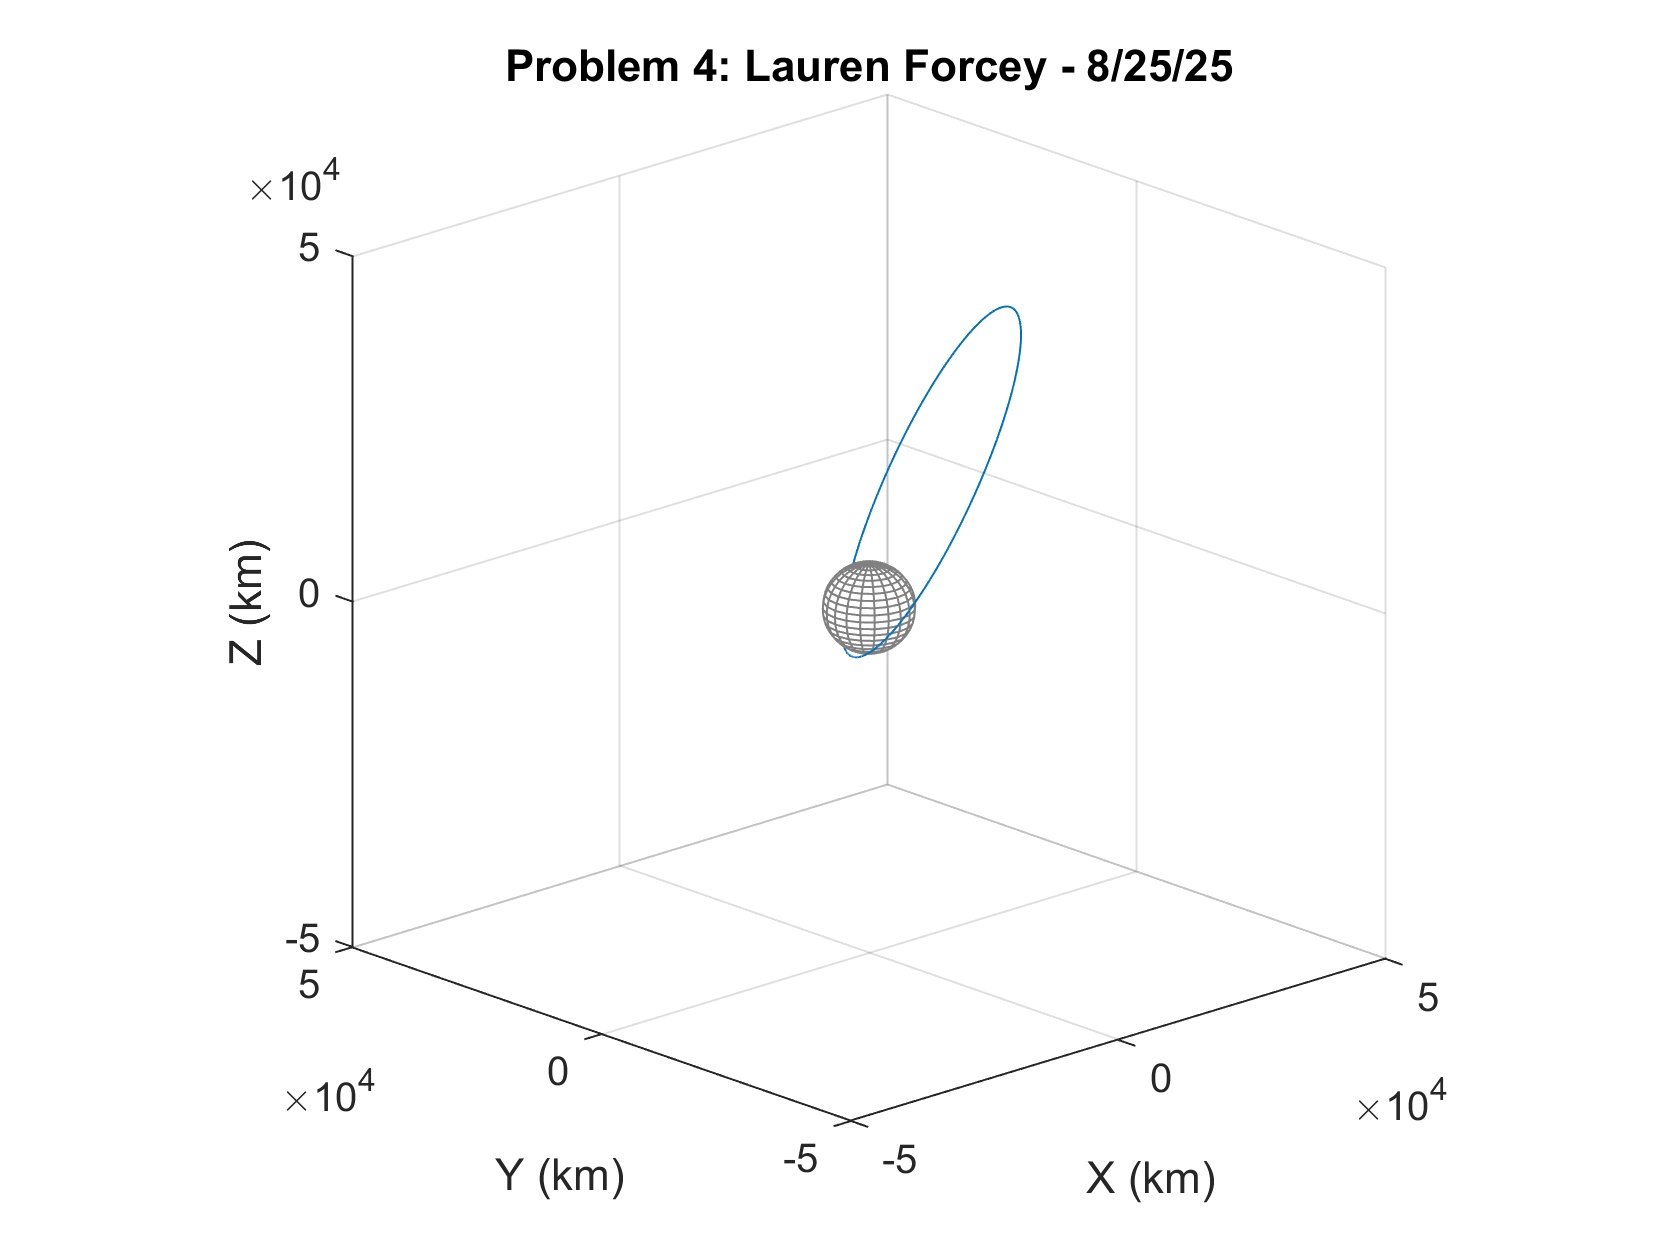


% state vec : col 1 = x, col 2 = y, col 3 = z
plot3(state(:,1), state(:,2), state(:,3))
title({'Problem 4: Lauren Forcey - 8/25/25'})
xlabel('X (km)')
ylabel('Y (km)')
zlabel('Z (km)')

% code block from hw to plot the earth as a sphere
% (copy pasted)
figure(1)
npanels=20;
erad = 6378.1; % equatorial radius (km)
prad = 6356.8; % polar radius (km)
axis(5e4*[-1 1 -1 1 -1 1]);
view(-43,19);
grid;
hold on;
axis vis3d;
[xx,yy,zz ] = ellipsoid(0, 0, 0, erad, erad, prad,npanels);
globe = surf(xx, yy, -zz, 'FaceColor', 'w', 'EdgeColor',0.5*[1 1 1]);
hold off;


% =============================